# Experiment 4: Transfer Learning with ResNet-50

## Clear Environment

close all;
clear variables;
existing_GUIs = findall(0);
if length(existing_GUIs) > 1
    delete(existing_GUIs);
end
clc;

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assgn_1_best\CUB_200_2011\";

## Load All Images

imgFolder = folder + "images/";
imgTxtFolder = folder + "images.txt";
imageDS = imageDatastore(imgFolder, "IncludeSubfolders",true, "LabelSource","foldernames");
[f1, f2, f3, f4, f5] = splitEachLabel(imageDS, 0.2, 0.2, 0.2, 0.2);

numFolds = 5;
numClasses = 20;

## Load pretrained ResNet-50

requires Deep Learning Toolbox Model for ResNet-50

net       = resnet50;                                
inputSize = net.Layers(1).InputSize;
targetSize = inputSize(1:2);

## Build the layer graph and swap out the last 3 layers

lgraph = layerGraph(net);

% 1) New fully‐connected layer (20 classes)
newFc = fullyConnectedLayer(numClasses, ...
    'Name','fc20', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);

% 2) New softmax
newSoftmax = softmaxLayer('Name','softmax20');

% 3) New classification output
newClassOutput = classificationLayer('Name','classoutput20');

% Replace them
lgraph = replaceLayer(lgraph, 'fc1000', newFc);
lgraph = replaceLayer(lgraph, 'fc1000_softmax', newSoftmax);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_fc1000', newClassOutput);

## Enable GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7441412096 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Train the simple CNN model for each fold

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |        6.25% |        9.95% |       3.3727 |       3.1474 |      1.0000e-04 |
|       1 |          20 |       00:00:16 |       81.25% |       82.35% |       0.6155 |       0.5867 |      1.0000e-04 |
|       2 |          40 |       00:00:28 |       96.88% |       89.14% |       0.1423 |       0.3365 |      1.0000e-04 |
|       3 |          50 |       00:00:33 |       96.88% |              |       0.0880 |              |      1.0000

Accuracy for Run 1 is: 0.88889


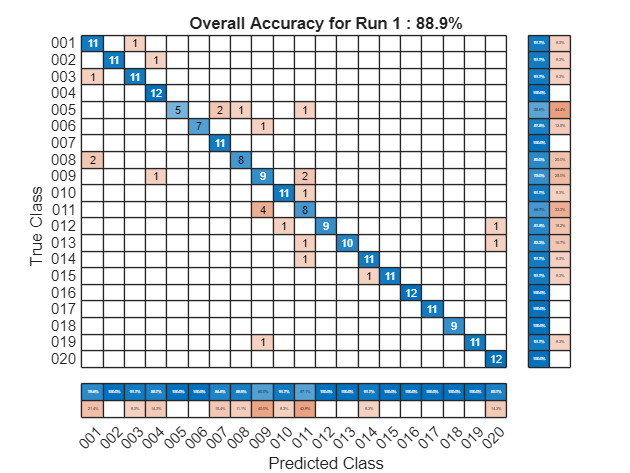

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        6.25% |        9.33% |       3.4741 |       2.9960 |      1.0000e-04 |
|       1 |          20 |       00:00:16 |       78.12% |       80.44% |       0.6633 |       0.6463 |      1.0000e-04 |
|       2 |          40 |       00:00:29 |       90.62% |       87.11% |       0.2367 |       0.4329 |      1.0000e-04 |
|       3 |          50 |       00:00:34 |      100.00% |              |       0.0313 |              |      1.0000

Accuracy for Run 2 is: 0.92889


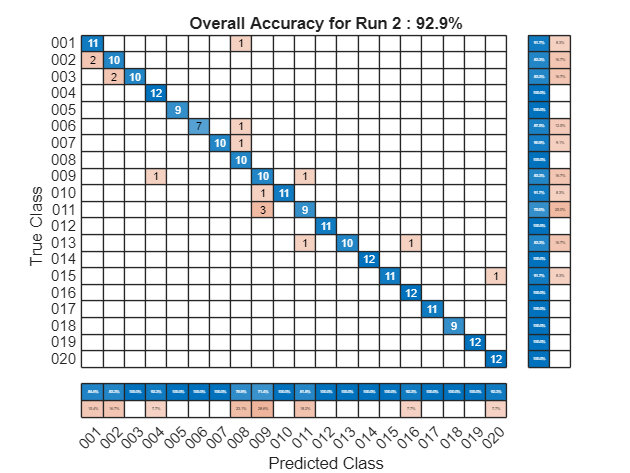

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        3.12% |       12.44% |       3.3194 |       2.9814 |      1.0000e-04 |
|       1 |          20 |       00:00:15 |       84.38% |       82.22% |       0.5288 |       0.5735 |      1.0000e-04 |
|       2 |          40 |       00:00:28 |      100.00% |       86.67% |       0.0547 |       0.3283 |      1.0000e-04 |
|       3 |          50 |       00:00:34 |      100.00% |              |       0.0086 |              |      1.0000

Accuracy for Run 3 is: 0.91403


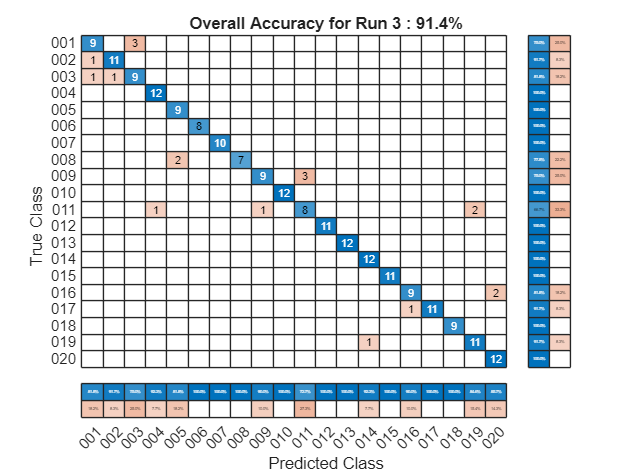

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |        9.38% |       14.93% |       3.3303 |       3.0136 |      1.0000e-04 |
|       1 |          20 |       00:00:24 |       87.50% |       83.26% |       0.4386 |       0.5412 |      1.0000e-04 |
|       2 |          40 |       00:00:45 |       93.75% |       91.40% |       0.2769 |       0.2915 |      1.0000e-04 |
|       3 |          50 |       00:00:55 |      100.00% |              |       0.0245 |              |      1.0000

Accuracy for Run 4 is: 0.89686


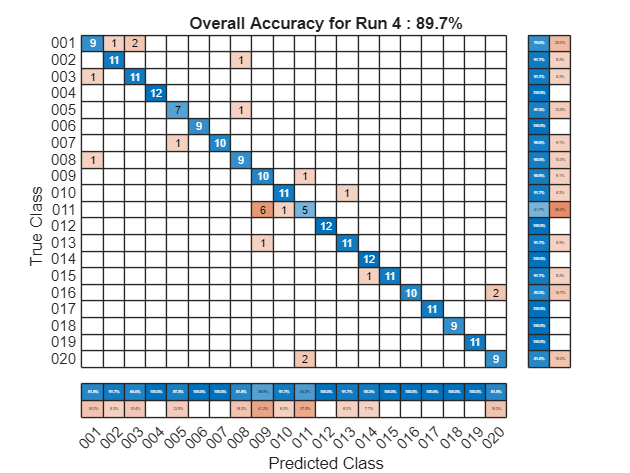

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        0.00% |       10.31% |       3.7479 |       3.1866 |      1.0000e-04 |
|       1 |          20 |       00:00:16 |       81.25% |       82.51% |       0.6447 |       0.6322 |      1.0000e-04 |
|       2 |          40 |       00:00:29 |      100.00% |       88.79% |       0.0657 |       0.3932 |      1.0000e-04 |
|       3 |          50 |       00:00:34 |      100.00% |              |       0.0607 |              |      1.0000

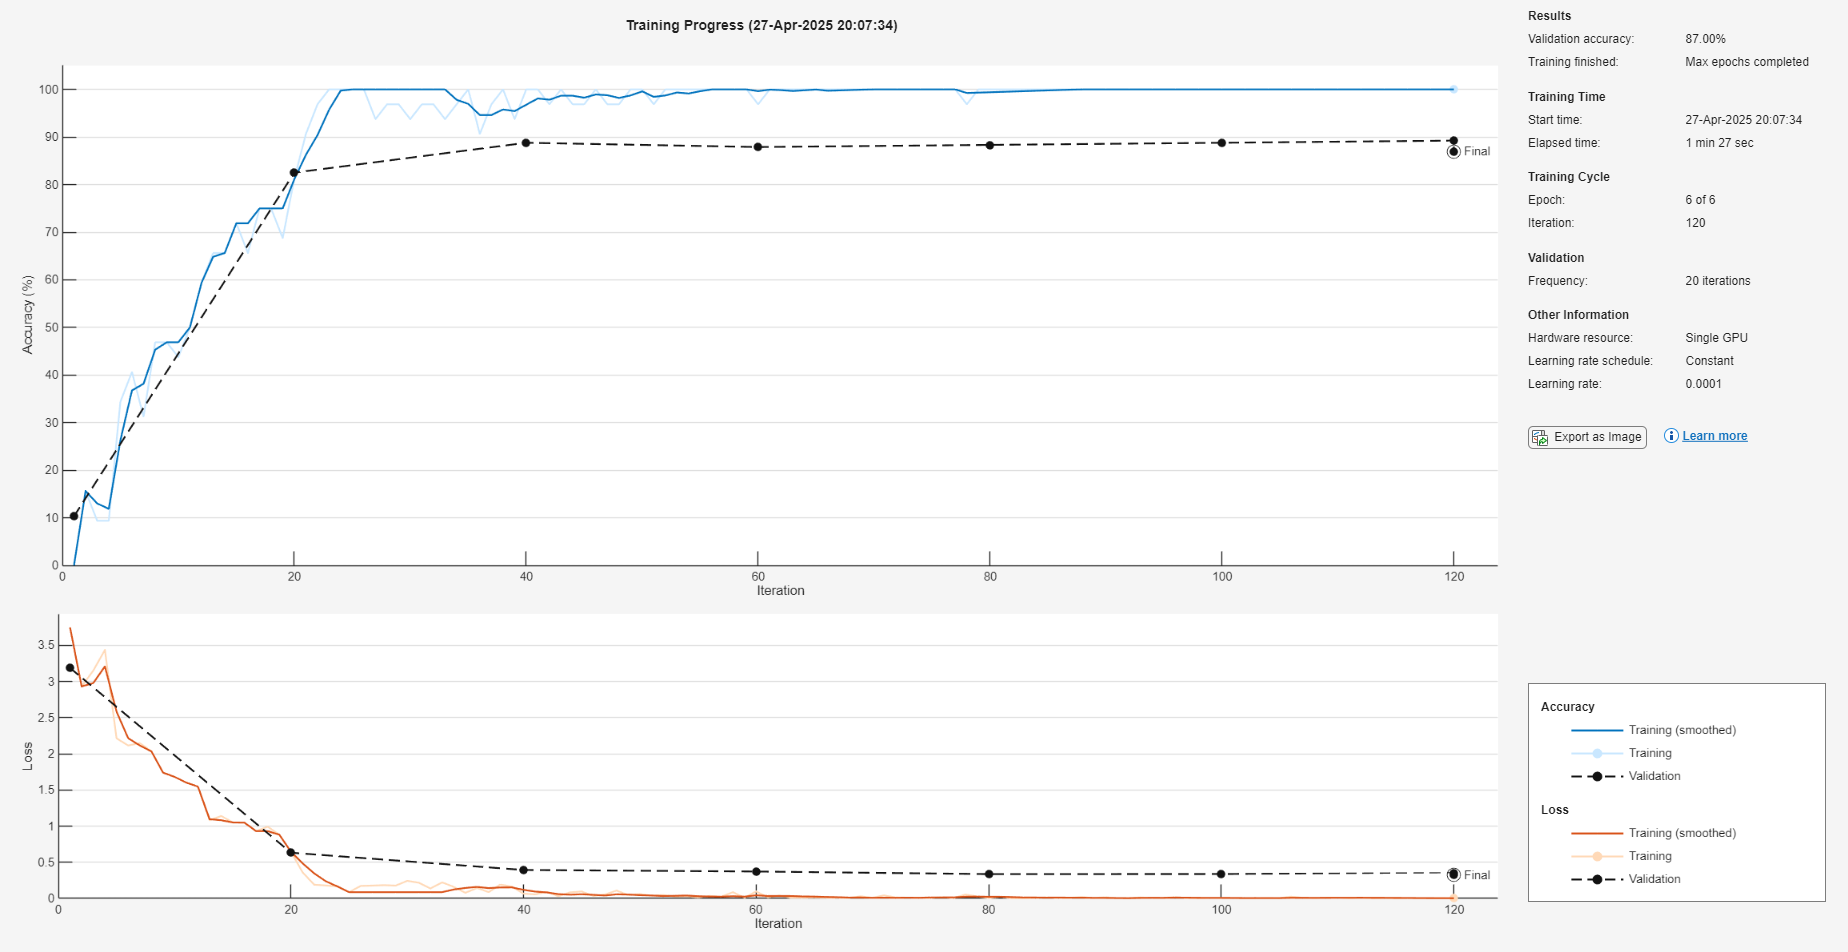

Accuracy for Run 5 is: 0.92308


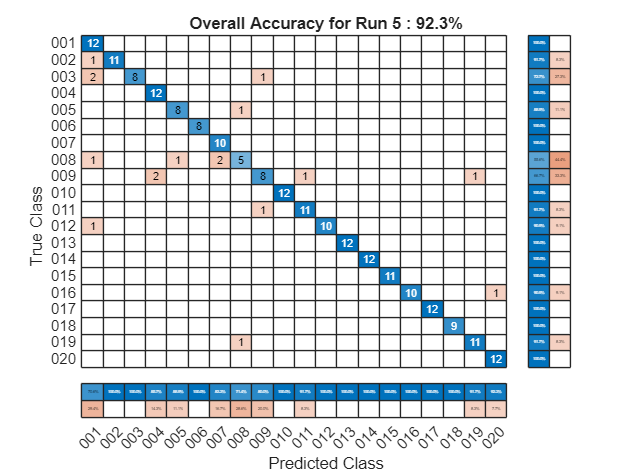

accuracy_overall = 0.0;
for i = 1:numFolds
    [cdsTraining, cdsValidation, cdsTest, trainingImageDS, validationImageDS, testImageDS] = ...
        getFoldsFor5FoldCrossVal(i, f1, f2, f3, f4, f5, folder, imgTxtFolder, targetSize);

    % Set the training options
    options = trainingOptions('adam', ...
    'MiniBatchSize',32, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',cdsValidation, ...
    'ValidationFrequency',floor(numel(trainingImageDS.Files)/32), ...
    'Verbose',true, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment','gpu');

    resnet20 = trainNetwork(cdsTraining, lgraph, options);

    YPred = classify(resnet20, cdsTest);
    YTest = testImageDS.Labels;
    
    accuracy = sum(YPred == YTest)/numel(YTest); % Output on command line
    disp("Accuracy for Run "+ string(i)+" is: " + accuracy);

    % Show confusion matrix in figure
    [m, order] = confusionmat(YTest, YPred);
    figure(i);
    cm = confusionchart(m, order, ...
        'ColumnSummary','column-normalized', ...
        'RowSummary','row-normalized');
    title("Overall Accuracy for Run "+ string(i)+" : "+ ...
        string(round(accuracy*100, 1)) +"%");

    accuracy_overall = accuracy_overall+accuracy;
end


disp("Average accuracy of five folds is "+ string(accuracy_overall/numFolds))

Average accuracy of five folds is 0.91035
